# Example Probabilistic Behaviour of Optimality gap

How does optimality gap behaves while updating probabilities? Can it be helpful for a most efficient communication chain planning? 

Let us first **Initializate a communication chain,**

p = 8; 
resource_allocation = 15;
n_trials = ones(1,p);
p_success = rand(1,p)

p_success =     0.3024    0.3340    0.6725    0.2630    0.8457    0.2257    0.1582    0.9962


Let us first see the effect of extra resource allocation on optimality gap:

random_agent = randperm(length(p_success), 1)

random_agent = 1

alpha = zeros(1,resource_allocation);
for i=1:resource_allocation
    n_trials(random_agent) = n_trials(random_agent)+1;
    alpha(i) = optimality_gap(p_success,n_trials);
end

let us plot this

fprintf("The behaviour of optimality gap with the reinforcement of agent %.2\n",random_agent)

The behaviour of optimality gap with the reinforcement of agent 

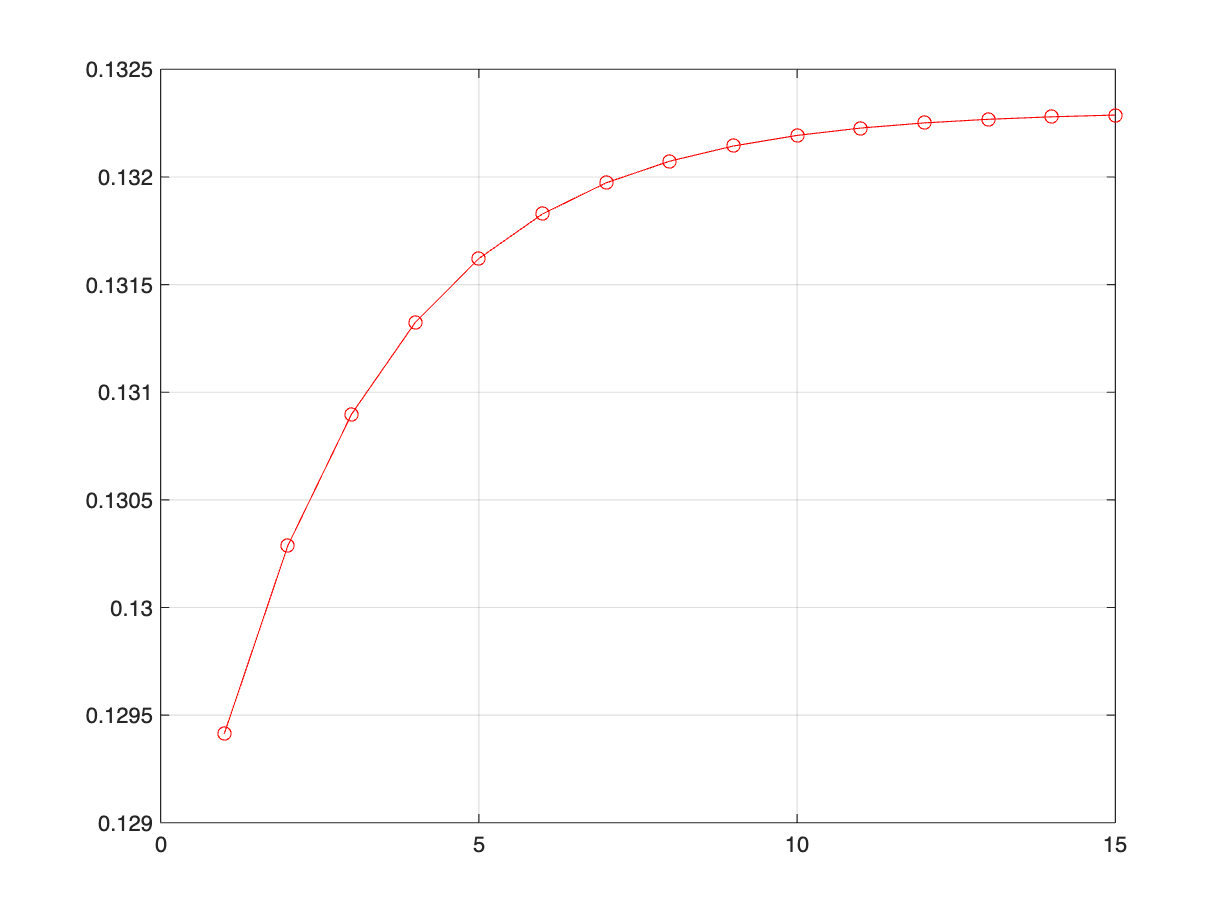

plot(alpha, '-ro'); 
grid on;

Now, let us show that the best agent to reinforce changes as resources are assigned,

reinforcement_list = zeros(1,resource_allocation); n_trials = ones(1,p);
for resource=1:resource_allocation
    results = rand(1, p); % save f_val and alpha for the reinforcement of each agent
    for idx = 1:p
        n_trials_i = n_trials;
        n_trials_i(idx) = n_trials_i(idx)+1;
        alpha = optimality_gap(p_success,n_trials_i);
        % save the values
        results(1,idx) = alpha;
    end
    [~,best_agent] = max(results(1,:));
    n_trials(best_agent) = n_trials(best_agent) + 1;
    reinforcement_list(resource) = best_agent;
end

let us plot this

fprintf("Evolution of reinforced agent\n")

Evolution of reinforced agent


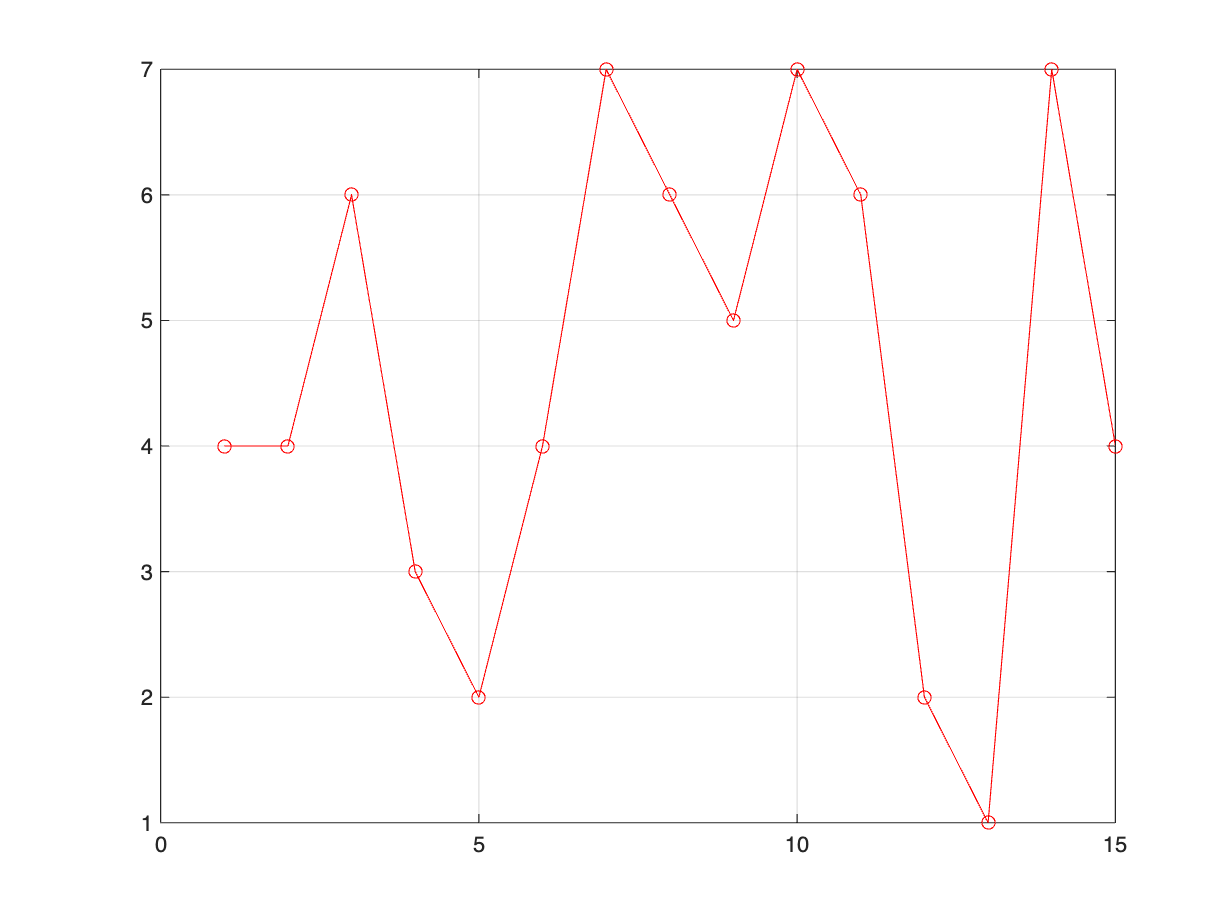

plot(reinforcement_list, '-ro'); 
grid on;

Finally, let us proof submodularity experimentally by marginal gain 

epochs = 500; marginals = zeros(1,epochs);
for epoch=1:epochs
    p = round(10 + (20-10)*rand(1));
    p_success = rand(1,p);
    % find two different lists S_1 \subseteq S_2 \subseteq S and a value x \in
    % S \setminus S_2
    values = sort(randperm(p, 3));
    S_1 = p_success(1:values(1));
    S_2 = p_success(1:values(2));
    x = p_success(values(3));
    % compute marginals
    [~,alpha_10] = probabilistic_force(S_1); [~,alpha_11] = probabilistic_force([S_1,x]); 
    [~,alpha_20] = probabilistic_force(S_1); [~,alpha_21] = probabilistic_force([S_2,x]); 
    margin_1 = alpha_11 - alpha_10; margin_2 = alpha_21 - alpha_20;
    % save the solution
    marginals(1,epoch) = margin_1-margin_2;
end

let us plot this

if (min(marginals)>0)&&(max(marginals)>0)
    fprintf("The chain construction is submodular!")
elseif (min(marginals)<0)&&(max(marginals)<0)
    fprintf("The chain construction is supermodular!")
else
    fprintf("The chain construction is undefined")
end

The chain construction is submodular!

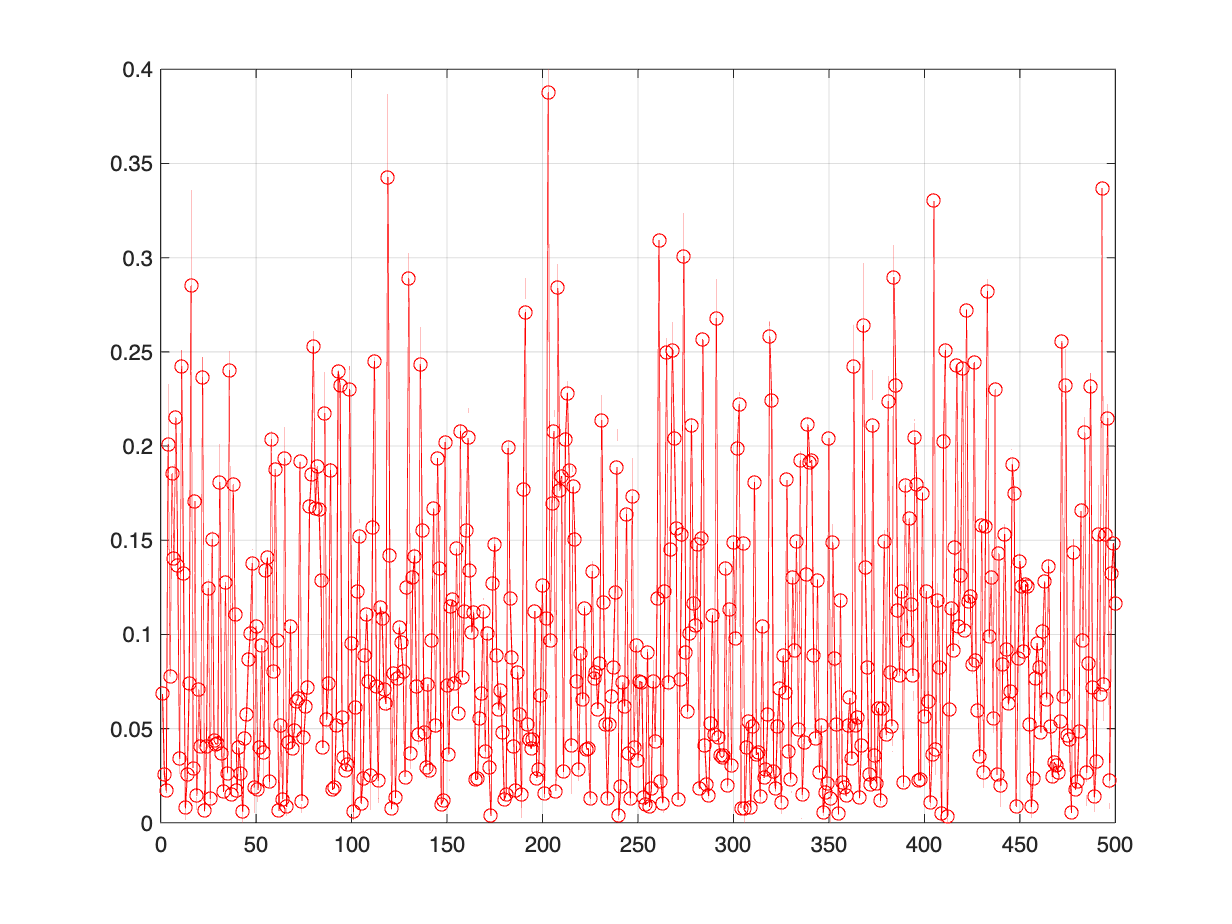

plot(marginals, '-ro'); 
grid on;